# Getting Started with RTI Connext for DDS Blockset - Arm Support Package

Thank you for downloading the RTI Connext® for DDS Blockset - Arm® Support Package. As developer of the market-leading DDS-based software, RTI is committed to developing tools and accelerators to enable productivity for Connext users across a variety of platforms. We have created a toolbox for Arm environments to make possible the deployment on these systems. Please view the instructions below and contact [support@rti.com](mailto:support@rti.com) if you run into any difficulties.

## Finishing Configuration

The RTI Connext Arm Support Package toolbox requires extra configuration for first-time use after the installation. This configuration requires that the environment variable NDDSHOME is set to a supported version. The latest version of the[ RTI Connext for DDS Blockset](https://www.mathworks.com/matlabcentral/fileexchange/94665-rti-connext-dds-connectivity-framework-for-dds-blockset) toolbox is preset to this. The configuration is automatically done by calling the following function in MATLAB®:

configure_rti_connext_dds_arm();

This command will install the corresponding Connext Arm libraries, if needed.

You only need to do this once after the installation.

## Prerequisites

This toolbox assumes that you have the following cross compilers correctly installed, and they are reachable in the PATH:

Windows® Systems:

- Arm 32 bits: arm-none-linux-gnueabihf-gcc and arm-none-linux-gnueabihf-g++

- Arm 64 bits: aarch64-none-linux-gnu-gcc and aarch64-none-linux-gnu-g++

Linux® Systems:

- Arm 32 bits: arm-linux-gnueabihf-gcc and arm-linux-gnueabihf-g++

- Arm 64 bits: aarch64-linux-gnu-gcc and aarch64-linux-gnu-g++

## Building Simulink Models for Arm 

This toolbox installs two new toolchains that allows the software to build the Simulink® model for Arm hardware (32 and 64 bits). It currently supports armv7Linux4gcc7.5.0 and armv8Linux4gcc7.3.0. These new toolchains will appear while configuring the DDS Blockset in Simulink, or by clicking in the 'Quick Start' button of the DDS Blockset:

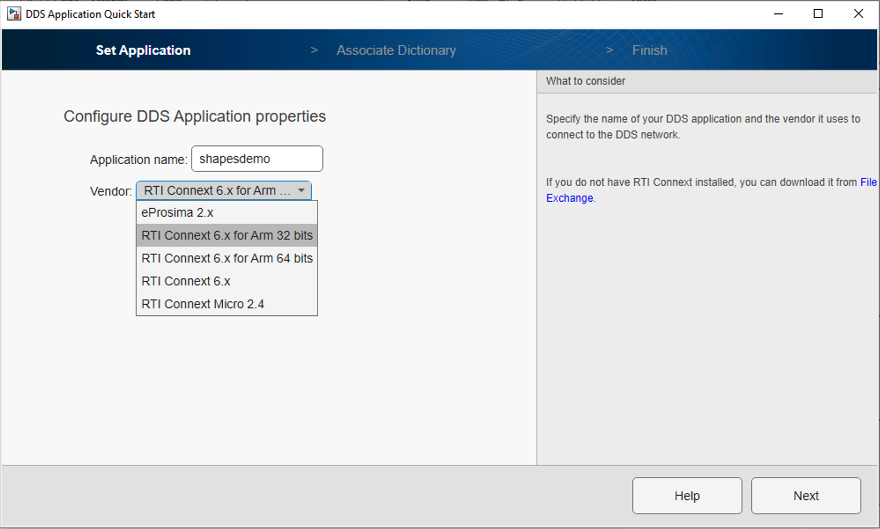

Depending on the toolchain selected, the corresponding RTI architecture will be used to build your Simulink application:

- RTI Connext 6.x for Arm 32 bits: armv7Linux4gcc7.5.0

- RTI Connext 6.x for Arm 64 bits: armv8Linux4gcc7.3.0

When cross-compiling for Arm, ensure that gmake/make is available in the PATH. In Windows systems, this may not be the case. If that's so, the RTI Connext for DDS Blockset - Arm Support Package will utilize the gmake version included in the MATLAB installation, for example: `<MATLAB path>\bin\win64\gmake.exe`.

If you prefer to specify a different gmake installation, set the environment variable `CONNEXT_ARM_TOOLBOX_GMAKE_PATH` to point to the desired gmake executable and then configure the RTI Connext for DDS Blockset - Arm Support Package again:

setenv('CONNEXT_ARM_TOOLBOX_GMAKE_PATH', '<Path_to_gmake.exe>');
configure_rti_connext_dds_arm();

## **Tested toolchains and platforms**

The following list outlines the combinations of tested toolchains and operating systems compatible with the RTI Connext for DDS Blockset - Arm Support Package toolbox. While the listed combinations have been verified, there are other toolchains and operating systems that should also work with this toolbox.

Arm 32 bits:

- OS: Raspberry Pi OS 32 bits based on debian Bookworm

- Toolchain: gcc-arm-10.3-2021.07-x86_64-arm-none-linux-gnueabihf

Arm 64 bits:

- OS: Raspberry Pi OS 64 bits based on debian Bullseye

- Toolchain: gcc-arm-10.2-2020.11-mingw-w64-i686-aarch64-none-linux-gnu

- OS: Raspberry Pi OS 64 bits based on debian Bookworm

- Toolchain: gcc-arm-10.3-2021.07-mingw-w64-i686-aarch64-none-linux-gnu

If you encounter any issues using this toolbox with a specific combination of toolchain and OS, please contact us at [simulink@rti.com](mailto:simulink@rti.com). 

## **Deployment**

This Arm Support Package generates an Arm executable for Arm 7 or Arm 8 that you need to copy to your device. This executable requires the XML file that is also generated (for example `shapesdemo_1.xml`). And you may also need to deploy the license file which is located in `$NDDSHOME/rti_license.dat`.

You can check where $NDDSHOME is pointing to:

getenv('NDDSHOME')

## License

The RTI Connext for DDS Blockset - Arm Support Package includes an evaluation version of the Connext libraries for Arm architecture. If you already have those libraries and a corresponding RTI Connext license, you can use those libraries and license for the RTI Connext for DDS Blockset - Arm Support Package toolbox. Please contact [RTI](http://www.rti.com/) if you need a production version of the RTI Connext Arm libraries. 

## Description

RTI Connext is a suite of software based on the Data Distribution Service standard (DDS) that enables applications to securely share information in real time and work as one integrated system. Connext provides a comprehensive software library, a set of development and monitoring tools, and many infrastructure services that support use cases including data record and replay, connect systems across wide area networks, bridge to other protocols, and integrate with cloud systems environments.

The MathWorks® DDS Blockset application is fully integrated with RTI Connext for easy development of Simulink applications that can be distributed on a network using DDS for communication. DDS Blockset provides engineers with DDS custom blocks to model DDS communication between Simulink and pure DDS applications without custom coding. System designers and application developers can incorporate RTI Connext into their Simulink designs as virtual components, ready to connect to other Simulink and non-Simulink components through the DDS databus. Users can generate code from Simulink models and deploy their models integrated with RTI Connext.

## System Requirements

The RTI Connext for DDS Blockset - Arm Support Package toolbox is supported on Linux and Windows systems as the host OS. RTI Connext may be deployed in a wide range of different OS and architectures. If you would like to use Connext with other platforms, please contact RTI ([https://www.rti.com/company/contact](https://www.rti.com/company/contact)).

## Features

RTI Connext Professional features:

- Fundamental communication pattern optimization in intelligent distributed systems including data-centric publish-subscribe, request-reply and queuing

- Fully compliant with the OMG® DDS for Real-Time Systems standard, including the DDS API and wire interoperability protocol (DDSI-RTPS)

- Superior performance for distributed applications through features such as zero-copy, Flat Data and data batching

- Routing Service for simplified bridging between data domains

- Recording Service to record and replay activity on the databus

- Monitoring and debugging tools to speed application development and deployment

- Data and network-level security. Authentication, Access Control, Integrity, message-level encryption, and data-level encryption (requires[ Connext DDS Secure](https://www.rti.com/products/connext-dds-secure)).

- Additional specifications available at[ www.rti.com/products/connext-6](http://www.rti.com/products/connext-6)